% Dynamical Model of two link Planar Manupulator 

% motor properties
amax=1.05; %[rad/s^2]

% link dimension
lx=[1 1];
ly=[1 1];
lz=[1 1];

%material properties
density= 2660 ; % [kg/m3] AW 5083 alloy
rho=(density*1000)/100^3; %[g/cm3]

mass=[rho*lx(1)*ly(1)*lz(1) rho*lx(2)*ly(2)*lz(2)];


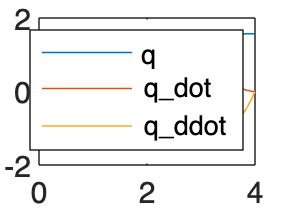

vand=@(t) [1 t t.^2 t.^3 t.^4 t.^5 t.^6 t.^7];
devand=@(t) [0 1 2*t 3*t^2 4*t^3 5*t^4 6*t^5 7*t^6];
dedevand=@(t) [0 0 2 6*t 12*t^2 20*t^3 30*t^4 42*t^5];
t_end = 4;
[A, vandermont] = criticaltrajectory(t_end, amax);

t = [0:0.01:t_end];
y = [];
for i=1:length(t)
    y=[y;A'*vand(t(i))', A'*devand(t(i))', A'*dedevand(t(i))'];
end
plot(t,y );
legend("q", "q\_dot", "q\_ddot");


J=linkjacobiansym(2, lx, ly, lz, rho);

[B, C] = dymsym(lx,ly,lz,rho);
C

$$C = \begin{array}{l} \left(\begin{array}{cc} 0 & {\mathrm{dq}}_{2}\,\sigma_{1}-{\mathrm{dq}}_{1}\,\left(\frac{25\,\cos\left(\bar{q_{1}}\right)}{266}-\frac{25\,\sin\left(\bar{q_{1}}\right)}{266}+\frac{25\,\cos\left(q_{1}\right)}{266}-\frac{25\,\sin\left(q_{1}\right)}{266}\right)\\ -{\mathrm{dq}}_{2}\,\sigma_{1} & {\mathrm{dq}}_{1}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\cos\left(q_{1}\right)\,\left(\frac{\sin\left(\bar{q_{1}}\right)}{2}-\frac{25}{133}\right)}{2}-\frac{\sin\left(q_{1}\right)\,\left(\frac{\cos\left(\bar{q_{1}}\right)}{2}-\frac{25}{133}\right)}{2}+\frac{\cos\left(\bar{q_{1}}\right)\,\left(\sin\left(q_{1}\right)-\frac{50}{133}\right)}{4}-\frac{\sin\left(\bar{q_{1}}\right)\,\left(\cos\left(q_{1}\right)-\frac{50}{133}\right)}{4} \end{array}$$

syms("q1","q2","dq1","dq2");
simplify(subs(C,[q1,q2,dq1,dq2],[pi/2,pi/2,0.1,0.1]))

$$ans = \left(\begin{array}{cc} 0 & \frac{5}{133}\\ -\frac{5}{266} & \frac{5}{266} \end{array}\right)$$

function [ Cx ,Cy ,Cz]= centerofmass(lx,ly,lz,rho)
 
    Cx= lx/rho;
    Cy= ly/rho;
    Cz= lz/rho;

end

%{
function [J]=linkjacobian(i,q,lx,ly,lz,rho)

    [Cx, Cy, Cz]= centerofmass(lx(i),ly(i),lz(i),rho);
    J=zeros(6,2);
    J(1,1)= -Cy;
    J(2,1)= Cx;
    J(6,1)= 1;

    if(i==2)
        J(1,2)=lx(i)*sin(q(1))-Cy;
        J(2,2)=Cx-lx(i)*cos(q(1));
        J(6,2)=1;
    end

end
%}

function [J]=linkjacobiansym(i,lx,ly,lz,rho)
    syms("q1");
    [Cx, Cy, Cz]= centerofmass(lx(i),ly(i),lz(i),rho);
    J=[0,0;0,0;0,0;0,0;0,0;0,q1];
    J(6,2)=0;
    J(1,1)= -Cy;
    J(2,1)= Cx;
    J(6,1)= 1;

    if(i==2)
        J(1,2)=lx(i)*sin(q1)-Cy;
        J(2,2)=Cx-lx(i)*cos(q1);
        J(6,2)=1;
    end

end









function [ inertia ] =linkinertia(i,lx,ly,lz,rho)

    [Cx, Cy, Cz]= centerofmass(lx(i),ly(i),lz(i),rho);
    %inertia = (lx(i)*ly(i)*lz(i)/12)*(ly(i)^2+lx(i)^2)*rho+...
        %lx(i)*ly(i)*lz(i)*rho*Cx;
    inertia = lx(i)*ly(i)*lz(i)*rho*((ly(i)^2+lx(i)^2)/12+Cx);

end

%{
function [T, R, p] = dh(q,lx)
q12=q(1)+q(2);
c12=cos(q12);
s12=sin(q12);
T=[ c12, -s12, 0, lx(1)*cos(q(1))+lx(2)*c12 ;
    s12 c12 0 lx(1)*sin(q(1))+lx(2)*s12;
    0 0 1 0;
    0 0 0 1];

R=[c12, -s12, 0;
   s12 c12 0 ;
   0 0 1 ];
p =[lx(1)*cos(q(1))+lx(2)*c12 ; lx(1)*sin(q(1))+lx(2)*s12 ; 0];

end
%}

function [T, R, p] = dhsym(lx)
syms("q1","q2");
q=[q1;q2];
q12=q(1)+q(2);
c12=cos(q12);
s12=sin(q12);
T=[ c12, -s12, 0, lx(1)*cos(q(1))+lx(2)*c12 ;
    s12 c12 0 lx(1)*sin(q(1))+lx(2)*s12;
    0 0 1 0;
    0 0 0 1];

R=[c12, -s12, 0;
   s12 c12 0 ;
   0 0 1 ];
p =[lx(1)*cos(q(1))+lx(2)*c12 ; lx(1)*sin(q(1))+lx(2)*s12 ; 0];

end

%{
function [ T ] = joint2op(q)
     
    q12=q(1)+q(2);
    c12=cos(q12);
    s12=sin(q12);

    T=[ 0 0 s12 ;
        0 1 0 ;
        1 0 c12];

end
%}




function [ T ] = joint2opsym()
    syms("q1","q2");
    q=[q1;q2];
    q12=q(1)+q(2);
    c12=cos(q12);
    s12=sin(q12);

    T=[ 0 0 s12 ;
        0 1 0 ;
        1 0 c12];

end

    

function [ A, vandermont ]= criticaltrajectory(tf, amax, b)
if(nargin <3)
b=[ -pi/2; 0; 0; pi/2; 0; 0; 0; amax];
end

vand=@(t) [1 t t^2 t^3 t^4 t^5 t^6 t^7];

devand=@(t) [0 1 2*t 3*t^2 4*t^3 5*t^4 6*t^5 7*t^6];

dedevand=@(t) [0 0 2 6*t 12*t^2 20*t^3 30*t^4 42*t^5];

vandermont= [ vand(0);
                devand(0);
                dedevand(0);
                vand(tf);
                devand(tf);
                dedevand(tf);
                vand(tf/2);
                dedevand(tf/4)];

A=(vandermont^-1)*b;

end



%{
function [ J ] =motorjacobian(i, q, lx )

J=zeros(6,2);

J(6,1)= 1;

if(i==2)

    J(1,1)=-lx*sin(q(1));
    J(2,1)=lx*cos(q(1));
    J(6,2)=1;

end

end

%}


function [ J ] =motorjacobiansym(i, q, lx )

syms("q1","q2");
    q=[q1;q2];

    J=[0,0;0,0;0,0;0,0;0,0;0,q1];
    J(6,2)=0;

J(6,1)= 1;

if(i==2)

    J(1,1)=-lx*sin(q(1));
    J(2,1)=lx*cos(q(1));
    J(6,2)=1;

end

end

%{
function [ B , C] = dym(q,lx,ly,lz,rho)
% B(i,j) = 0.5*m*J_p^T*J_p+0.5*J_o^T*R*I*R^T*J_o
B=0;
Rot = @(q) [cos(q), -sin(q), 0; sin(q), cos(q), 0; 0 0 1];
for i=1:2
    J = linkjacobian(i,q,lx,ly,lz,rho);
    J_p = J(1:3,:);
    J_o = J(4:end, :);
    R = eye(3);
    if(i == 2)
        R = Rot(q(1)+q(2));
    else
        R = Rot(q(1));
    end
    m=lx(i)*ly(i)*lz(i)*rho;
    I = linkinertia(i,lx,ly,lz,rho);
    B=B+0.5*J_p'*J_p+0.5*J_o'*R*I*R'*J_o;
    

end

end
%}

function [ B , C] = dymsym(lx,ly,lz,rho)
% B(i,j) = 0.5*m*J_p^T*J_p+0.5*J_o^T*R*I*R^T*J_o
syms("q1","q2", "dq1", "dq2");
q=[q1;q2];
dq=[dq1;dq2];
B=0;
Rot = @(q) [cos(q), -sin(q), 0; sin(q), cos(q), 0; 0 0 1];
for i=1:2
    J = linkjacobiansym(i,lx,ly,lz,rho);
    J_p = J(1:3,:);
    J_o = J(4:end, :);
    R = eye(3);
    if(i == 2)
        R = Rot(q(1)+q(2));
    else
        R = Rot(q(1));
    end
    m=lx(i)*ly(i)*lz(i)*rho;
    I = linkinertia(i,lx,ly,lz,rho);
    B=B+0.5*J_p'*J_p+0.5*J_o'*R*I*R'*J_o;
    
    
    
    C=[0, 0; 0, q1];
    C(2,2)=0;
    for i=1:2
        for j=1:2
            C(i,j)=0;
            for k=1:2
                C(i,j)=C(i,j)+0.5*(diff(B(i,j), q(k))-diff(B(i,k),q(j))+diff(B(j,k),q(i)))*dq(k);
            end
        end
    end

    %{
    TODO:
    - aggiungere energia cinetica motori
    - aggiungere energia potenziale di link e motori per calcolo di g(q)
    - facoltativo: aggiungere modellazione dell'attrito
    %}
    

end

end




